**LEP 9-5 : Bacterial growth in a Batch Reactor**

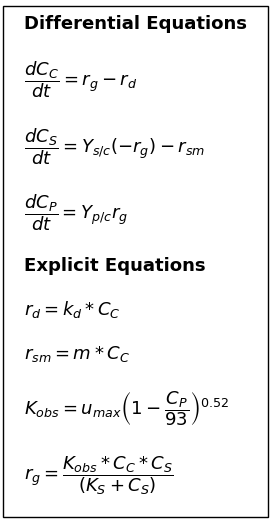

function dYfuncvecdD = ODEfun(D,Yfuncvec); 
Cc= Yfuncvec(1);
Cs= Yfuncvec(2);
mCc=Yfuncvec(3); %assume mCc is equal to DCc

%kd=0.08;
Ysc=12.5;
% Ypc=5.6;
Ks=42.5;
% m=0.03;
umax=0.36;
v_0 =0.1;
V =0.25;
Cso =70.32;
%Cco =80.62;
warning('off','all')

%D = v_0/V;

%Ycs= 1/Ysc;

Ycs= Cc/(Cso- ((v_0/V).* Ks )./ (umax - (v_0/V)));

Cs = D * Ks ./ (umax - D);

%u= umax * Cso / (Ks + Cso);

D_crit = umax * Cso / (Ks + Cso);

D_opt = umax * (1 - (Ks / (Ks + Cso))^.5);

%display(Ycs);
display(D_crit);
display(D_opt);
% e= Yfuncvec(3);
% Explicit equations
% D =v_0/V;
% alpha = .0001;
% beta = .05;
% Ks = .1 ;
% mumax = .9;
% emax = alpha/(mumax+beta);
% ER = e/emax;
% u = umax *Cs/(Ks + Cs);
% Differential equations
dCcdD= Ycs*(Ks/((v_0/V) - umax) - ((v_0/V)*Ks)/((v_0/V) - umax)^2);
dCsdD = Cso - Cs;
dmCcdD = Ycs*(Cso + ((v_0/V)*Ks)/((v_0/V) - umax)) + (v_0/V)*Ycs*(Ks/((v_0/V) - umax) - ((v_0/V)*Ks)/((v_0/V) - umax)^2);
% dedt = alpha * Cs/(Ks + Cs) - beta*e - mu*e;
dYfuncvecdD=[dCcdD;dCsdD;dmCcdD];
end
